# Image Processing

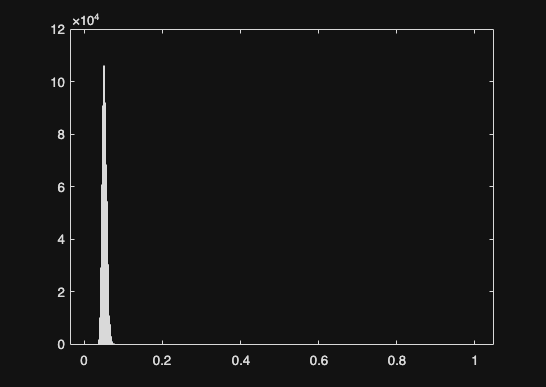

img = im2double(imread('raw/20250321T192416_651_StackInput.tiff'));

histogram(img);

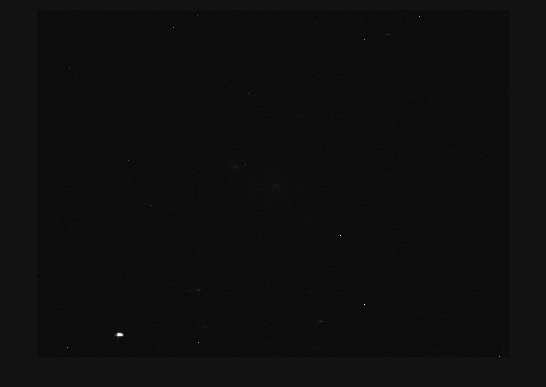

imshow(img);

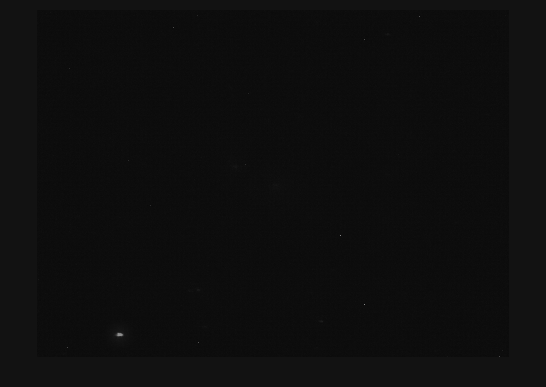


img_smooth = imgaussfilt(img, 30);   % keep only smooth sky
grid_pattern = img - img_smooth;     % isolate the fine grid
img = img - grid_pattern*.5;
img(img<0) = 0;
imshow(img);

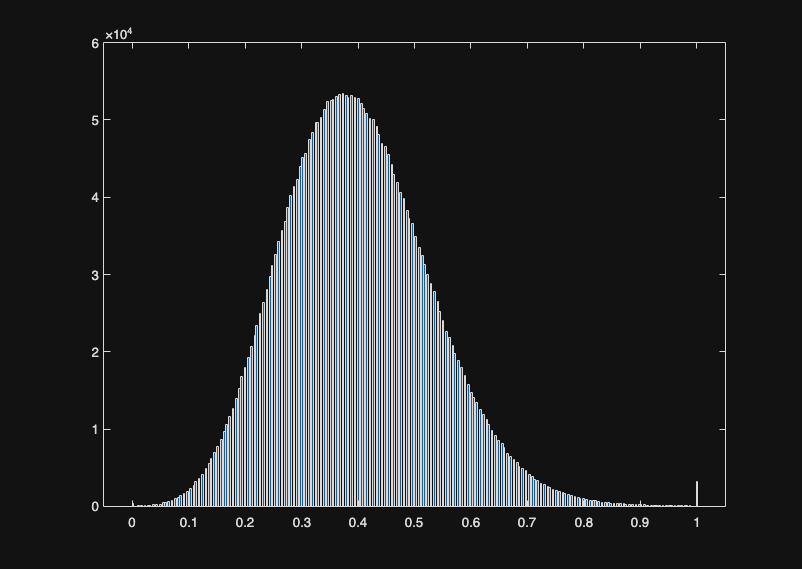

enhancedImg = enhance_contrast(img);
histogram(enhancedImg);

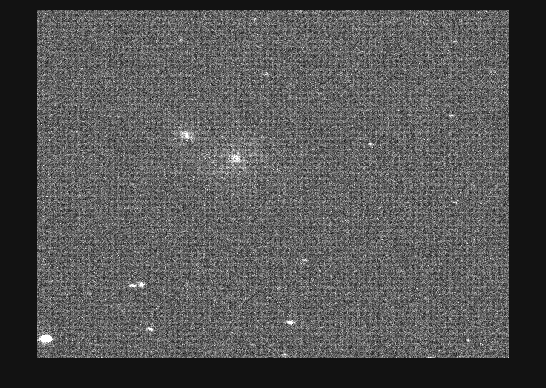

imshow(enhancedImg);

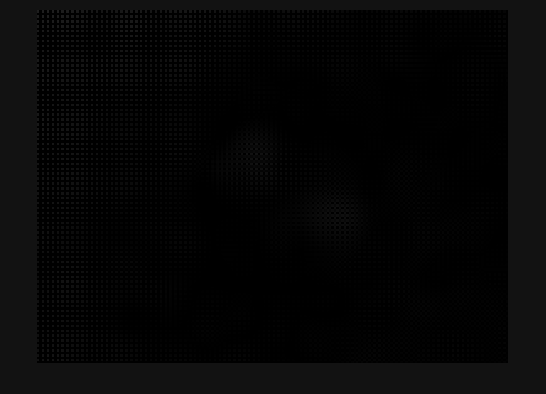

background = im2double(imread("background_fit.tiff"));

background_smooth = imgaussfilt(background, 30);   % keep only smooth sky
grid_pattern = background - background_smooth;     % isolate the fine grid
imshow(grid_pattern)